% load data
fs = 16000;
internal_overlapping = 0.0;


perf_dir = "D:\Sber\"; 
classificator_l = read_json(perf_dir);

Выбран файл: D:\Sber\dnn\4 - CNN4\combi\flight_task\pan_l\fly_phantom06_sg_l\performance\bn_cnn4_3c-combi-1.0-0.5-mel-64-2048-512-predictions.json


pred_l = extrapolate_predictions(fs, internal_overlapping, classificator_l);
classificator_r = read_json(perf_dir);

Выбран файл: D:\Sber\dnn\4 - CNN4\combi\flight_task\pan_r\fly_phantom06_sg_r\performance\bn_cnn4_3c-combi-1.0-0.5-mel-64-2048-512-predictions.json


pred_r = extrapolate_predictions(fs, internal_overlapping, classificator_r);

current_pos =99

current_pos = 99

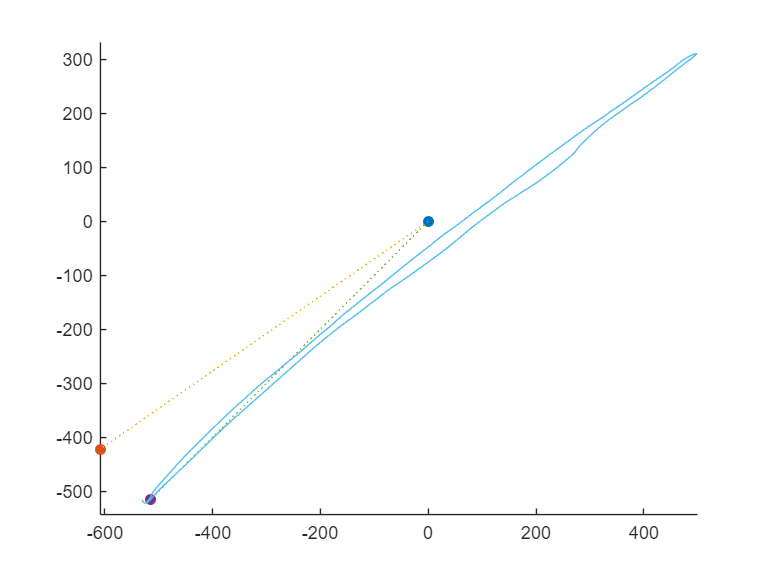

figure('Name', 'Flight Task Trajectory');
hold on
scatter(ref_point_east, ref_point_north, "filled")
scatter(pan_l_east, pan_l_north, "filled")
plot([ref_point_east pan_l_east], [ref_point_north pan_l_north], ':')
scatter(pan_r_east, pan_r_north, "filled")
plot([ref_point_east pan_r_east], [ref_point_north pan_r_north], ':')
pos_idx = round(current_pos*length(uav_east)/100);
plot(uav_east(1:pos_idx), uav_north(1:pos_idx))
axis('equal');

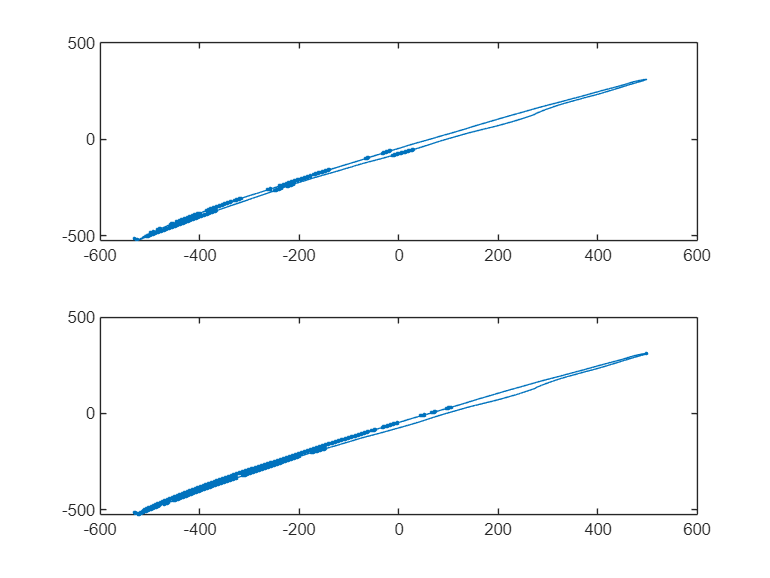

% Detections
figure('Name', 'Original detections');
subplot(2,1,1)
plot(uav_east(1:pos_idx), uav_north(1:pos_idx), 'MarkerIndices', find(pred_l.predictions(1:pos_idx)), 'marker','.')
subplot(2,1,2)
plot(uav_east(1:pos_idx), uav_north(1:pos_idx), 'MarkerIndices', find(pred_r.predictions(1:pos_idx)), 'marker','.')

% Thresholded detections
threshold = 40

threshold = 40

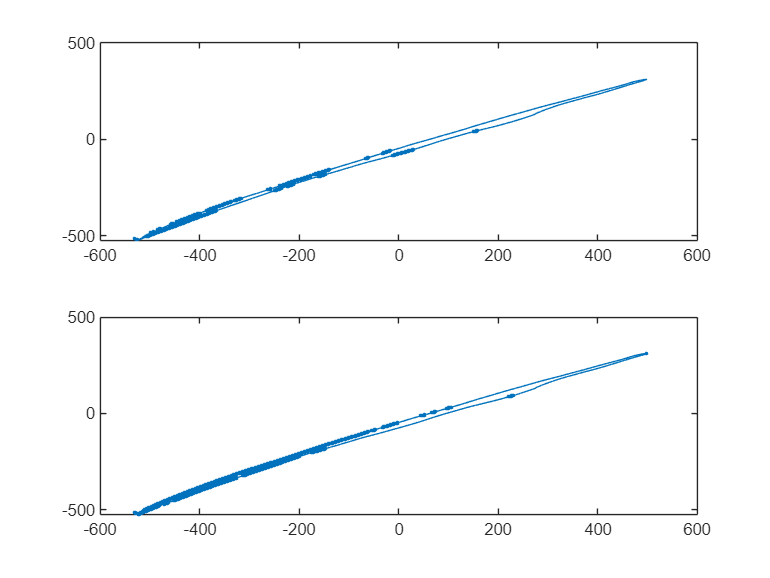

predict_l = pred_l.probability(1:pos_idx,2) >= threshold / 100;
predict_r = pred_r.probability(1:pos_idx,2) >= threshold / 100;

figure('Name', 'Threshold-based detections');
subplot(2,1,1)
plot(uav_east(1:pos_idx), uav_north(1:pos_idx), 'MarkerIndices', find(predict_l(1:pos_idx)), 'marker','.')
subplot(2,1,2)
plot(uav_east(1:pos_idx), uav_north(1:pos_idx), 'MarkerIndices', find(predict_r(1:pos_idx)), 'marker','.')

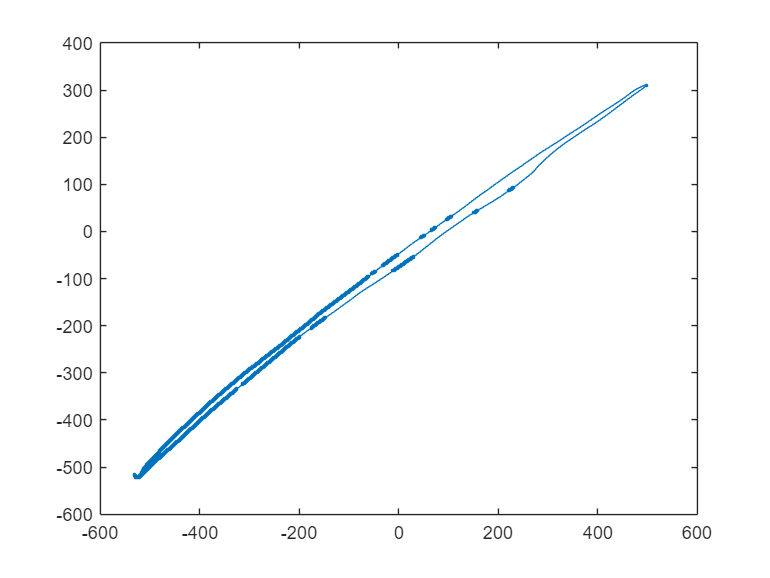

% PAN Fusion 1
predict_f1 = predict_l | predict_r;

figure('Name', 'Naive Fusion Detections');
plot(uav_east(1:pos_idx), uav_north(1:pos_idx), 'MarkerIndices', find(predict_f1(1:pos_idx)), 'marker','.')

% PAN Fusion 2
window = 10

window = 10

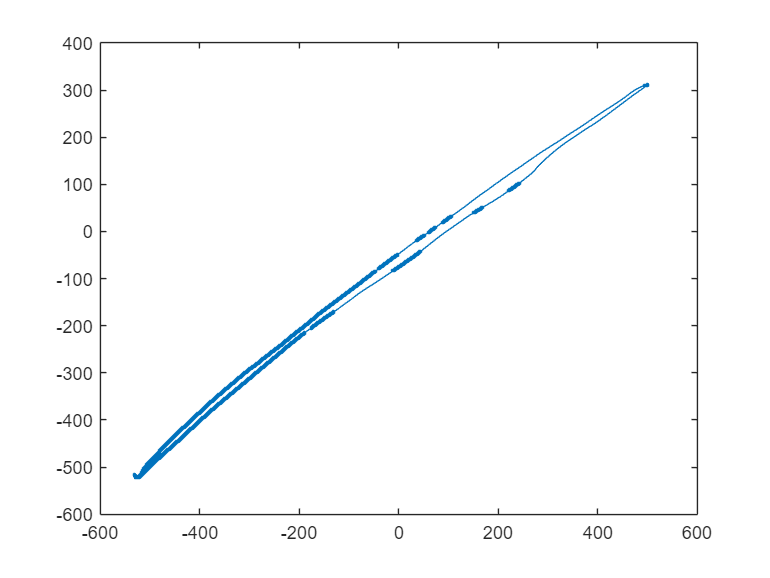

predict_f2 = sliding_or(predict_l, predict_r, window*fs/10);

figure('Name', 'Sliding Window Fusion Detections');
plot(uav_east(1:pos_idx), uav_north(1:pos_idx), 'MarkerIndices', find(predict_f2(1:pos_idx)), 'marker','.')

sliding_threshold = 25

sliding_threshold = 25

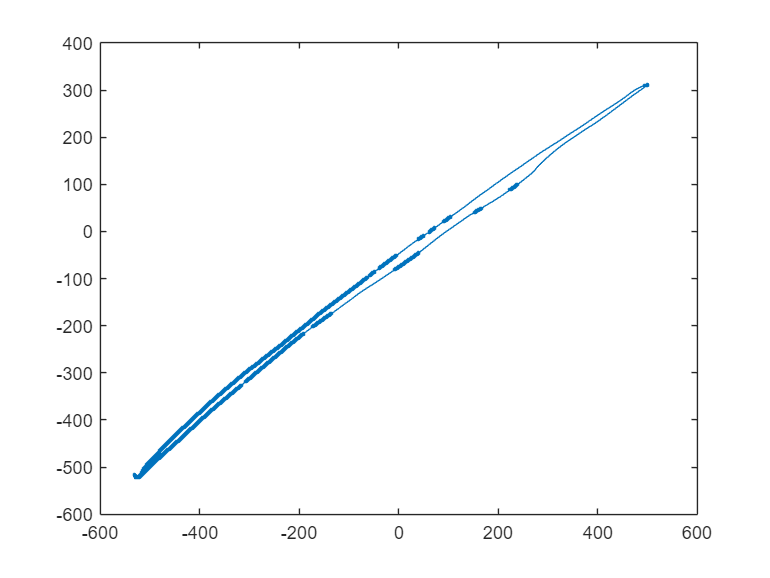

predict_f3 = sliding_statistics(predict_l, predict_r, window*fs/10, sliding_threshold);

figure('Name', 'Sliding Statistics Fusion Detections');
plot(uav_east(1:pos_idx), uav_north(1:pos_idx), 'MarkerIndices', find(predict_f3(1:pos_idx)), 'marker','.')